## Funciones

### Funciones que retornan mas de un valor

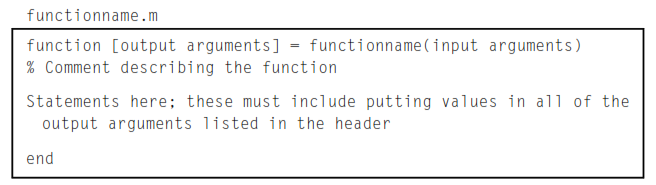

sumar(12, 13)

ans = 25

Ejemplo de una función que calcula dos valores, área y circunferencia de un círculo; esto está almacenado en un archivo llamado areacirc.m:


[a, c] = areacirc(4)

a = 50.2655

c = 25.1327

Si no indica donde se captura los resultados se regresa un sólo resultado. 

areacirc(4)

ans = 50.2655

Se puede intentar pasar un vector a la funsión areacirc

[a, c] = areacirc(1:4)

a =     3.1416   12.5664   28.2743   50.2655


c =     6.2832   12.5664   18.8496   25.1327


En el caso que se requiera solo la segunda salida

[~, c] = areacirc(1:4)

c =     6.2832   12.5664   18.8496   25.1327


La documentación que se agrego se puede observar a tráves de la función help

help areacirc

 areacirc regresa el area y circunferencia de un circulo
  Formato: areacirc(radius)



Las funciones se puede llamar desde la ventana de comandos o desde un script

[r, e, p] = ingreso_datos()

r = 11

e = 12

p = 1

La siguiente función agrega un elemento al final 

a = [1, 2, 3, 4]

a =      1     2     3     4


agregar(a)

ans =      1     2     3     4    12


a

a =      1     2     3     4


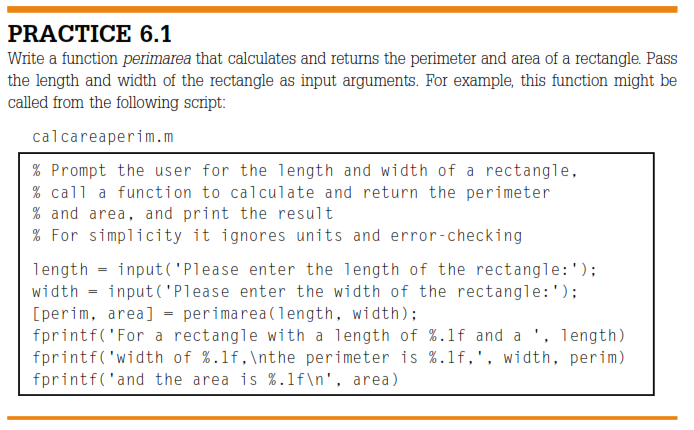

length = input('Please enter the lenght of the rectangle: ');
width = input('Please enter the width of the rectangle: ');
[perim, area] = perimarea(length, width);
fprintf('For a rectangle with a length of %.1f and a ', length)

For a rectangle with a length of 12.0 and a 

fprintf('width of %.1f,\nthe perimeter is %.1f.', width, perim)

width of 11.0,
the perimeter is 46.0.

fprintf('and the area is %.1f\n', area)

and the area is 132.0


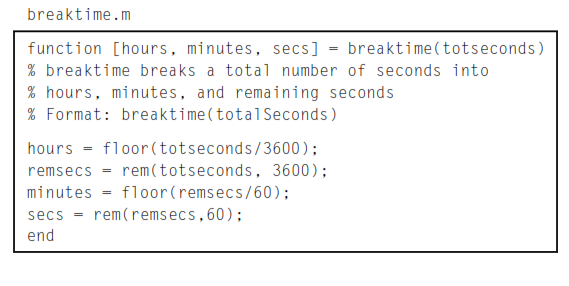

help breaktime

  breaktime break a total number of seconds into
  hours, minutes, and remaining seconds
  Format: breaktime(totalSeconds)



[h, m, s] = breaktime(1200)

h = 0

m = 20

s = 0

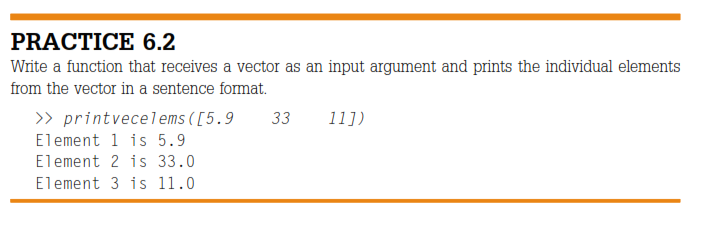

printvecelems([5.9 33 11])

Element 1 is 5.9
Element 2 is 33.0
Element 3 is 11.0


printvecelems(1:34)

Element 1 is 1.0
Element 2 is 2.0
Element 3 is 3.0
Element 4 is 4.0
Element 5 is 5.0
Element 6 is 6.0
Element 7 is 7.0
Element 8 is 8.0
Element 9 is 9.0
Element 10 is 10.0
Element 11 is 11.0
Element 12 is 12.0
Element 13 is 13.0
Element 14 is 14.0
Element 15 is 15.0
Element 16 is 16.0
Element 17 is 17.0
Element 18 is 18.0
Element 19 is 19.0
Element 20 is 20.0
Element 21 is 21.0
Element 22 is 22.0
Element 23 is 23.0
Element 24 is 24.0
Element 25 is 25.0
Element 26 is 26.0
Element 27 is 27.0
Element 28 is 28.0
Element 29 is 29.0
Element 30 is 30.0
Element 31 is 31.0
Element 32 is 32.0
Element 33 is 33.0
Element 34 is 34.0


### Funciones que regresan valores vs los que imprimen

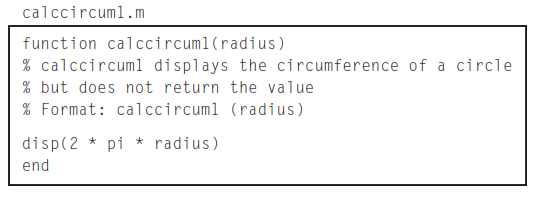

Lo correcto es así si deseamos realizar operaciones con los resultados de las funciones.

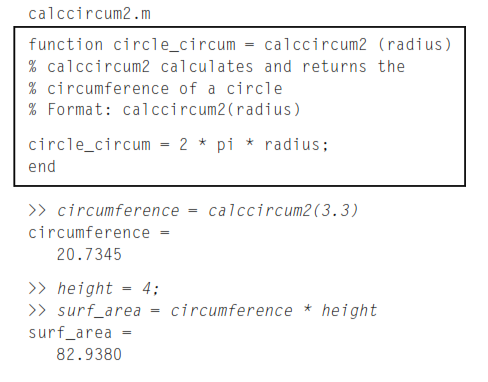

### Organización en modulos

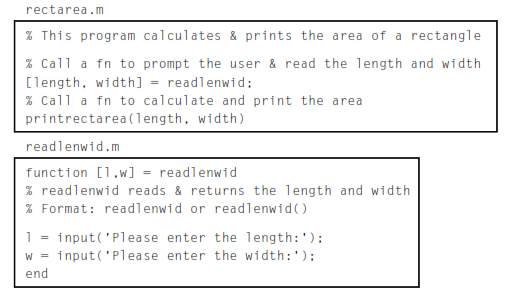

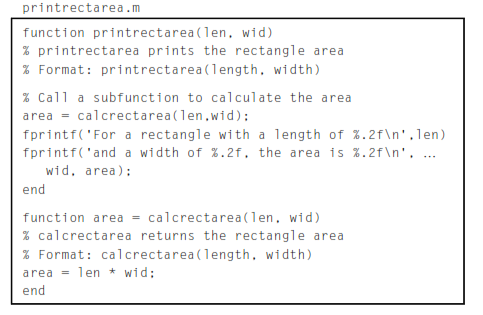

## Problemas

### Problema 1

Desarrollar una función que resuelva la ecuación de segundo grado. 


$${\textrm{ax}}^{2\;} +\textrm{bx}+c=0$$


La solución de la ecuación cuadrática están dadas por:


$$x_{1,2} =\frac{-b\pm \sqrt{b^2 -4\textrm{ac}}}{2a}$$


Solución para la ecuación $x^2 +2x+3=0$

[x1 x2] = cuadratica(1, 2, 3)

x1 = -1.0000 + 1.4142i

x2 = -1.0000 - 1.4142i

y para la ecuación $4x^2 +8x-60=0$

[x1, x2] = cuadratica(4, 8, -60)

x1 = 3

x2 = -5

Adicional, $2x{\;}^2 +5x+3=0$

[x1, x2] = cuadratica(2, 5, 3)

x1 = -1

x2 = -1.5000

### Problema 2

Definir una función para calcular el valor del polinomio $3x^3 +5x^2 -2x+1$

poly(4)

ans = 265

poly(1:10)

ans =            7          41         121         265         491         817        1261        1841        2575        3481


### Problema 3

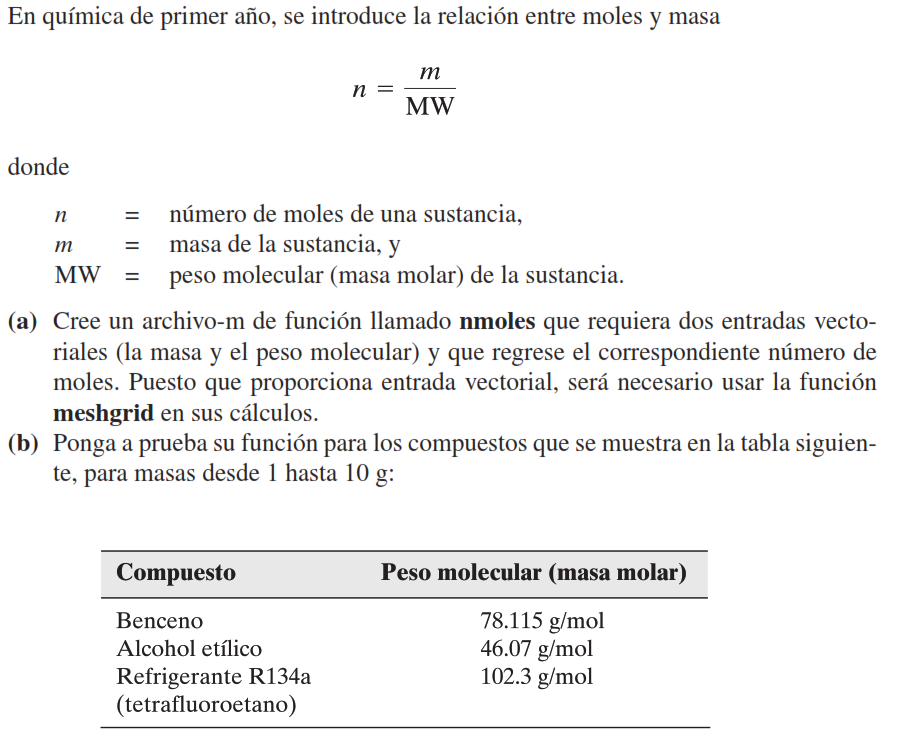

masas = 1:10

masas =      1     2     3     4     5     6     7     8     9    10


mw = [78.115 46.07 102.3]

mw =    78.1150   46.0700  102.3000


n = nmoles(masas, mw)

n =     0.0128    0.0256    0.0384    0.0512    0.0640    0.0768    0.0896    0.1024    0.1152    0.1280
    0.0217    0.0434    0.0651    0.0868    0.1085    0.1302    0.1519    0.1736    0.1954    0.2171
    0.0098    0.0196    0.0293    0.0391    0.0489    0.0587    0.0684    0.0782    0.0880    0.0978


### Problema 4

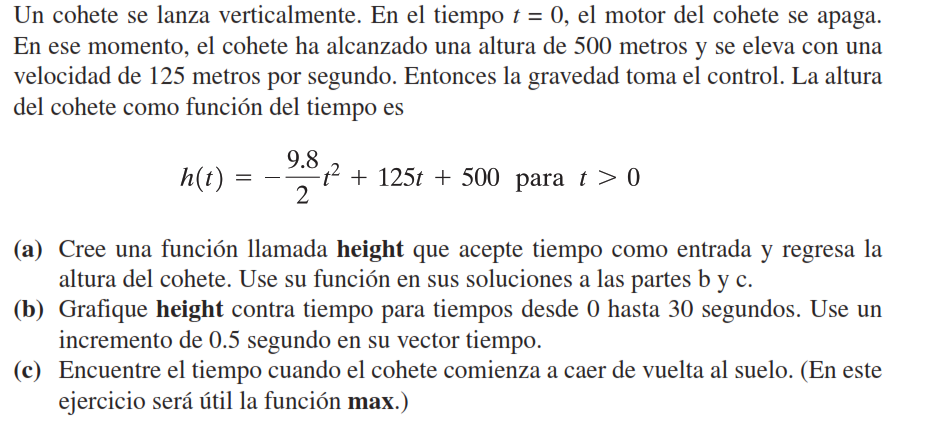

t = 0:0.5:30;
h = height(t);

plot(t, h);
xlabel("Tiempo (s)")
ylabel("Altura (m)")
grid on
altura_maxima = max(h)

altura_maxima = 1.2969e+03

tiempo_momento_caida = t(h == altura_maxima)

tiempo_momento_caida = 13

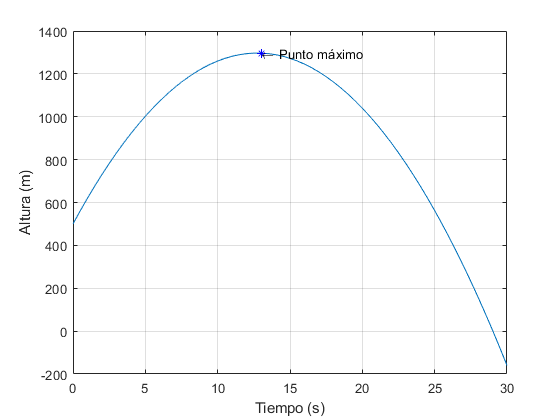

hold on

plot(tiempo_momento_caida, altura_maxima, 'b*')
text(tiempo_momento_caida, altura_maxima, '\leftarrow Punto máximo')

## **Variables de funciones**

Las variables del programa principal y de una función son independientes aunque tengan el mismo nombre.


a = 4;
b = 2;
c = 0.47;

fprintf('Las variables antes del la prueba son \n a = %g \n b = %g \n c = %g \n', a, b, c)

Las variables antes del la prueba son 
 a = 4 
 b = 2 
 c = 0.47 


prueba()

Acabo de entrar a prueba. 
Estoy dentro de la función: Las variables son 
 a = 1 
 b = 10 
 c = 100 
Saliendo de la función. 


ans = 3

fprintf('Estoy de regreso en el programa principal \n')

Estoy de regreso en el programa principal 


fprintf('Las variables son \n a = %g \n b = %g \n c = %g \n', a, b, c)

Las variables son 
 a = 4 
 b = 2 
 c = 0.47 


### **Variables declaradas como argumentos de la función (paso por valor)**

Podemos pasar valores de variables de un programa principal a una función y no a la inversa.

a = 4;
b = 2;
c = 0.47;
fprintf('Las variables antes del la prueba son \n a = %g \n b = %g \n c = %g \n', a, b, c)

Las variables antes del la prueba son 
 a = 4 
 b = 2 
 c = 0.47 


p = prueba2(a, b, c);

Estoy dentro de la función. 
Las variables son 
 a = 8 
 b = 20 
 c = 47 
Saliendo de la función.


fprintf('Estoy de regreso en el programa principal \n')

Estoy de regreso en el programa principal 


fprintf('Las variables son \n a = %g \n b = %g \n c = %g \n', a, b, c)

Las variables son 
 a = 4 
 b = 2 
 c = 0.47 
